# Práctica 2 - Cortocircuitos II - Apartado D

#### Corriente que circula por el interruptor I cuando se produce una falta bifásica a tierra (F20t) en el punto F2

## Sistemas Eléctricos y de Potencia

### Subgrupo 10

format shortG
sympref('FloatingPointOutput', true);
if ~exist('Sbase', 'var')
    evalc('Practica1A');
end

## Circuito equivalente en secuencia directa

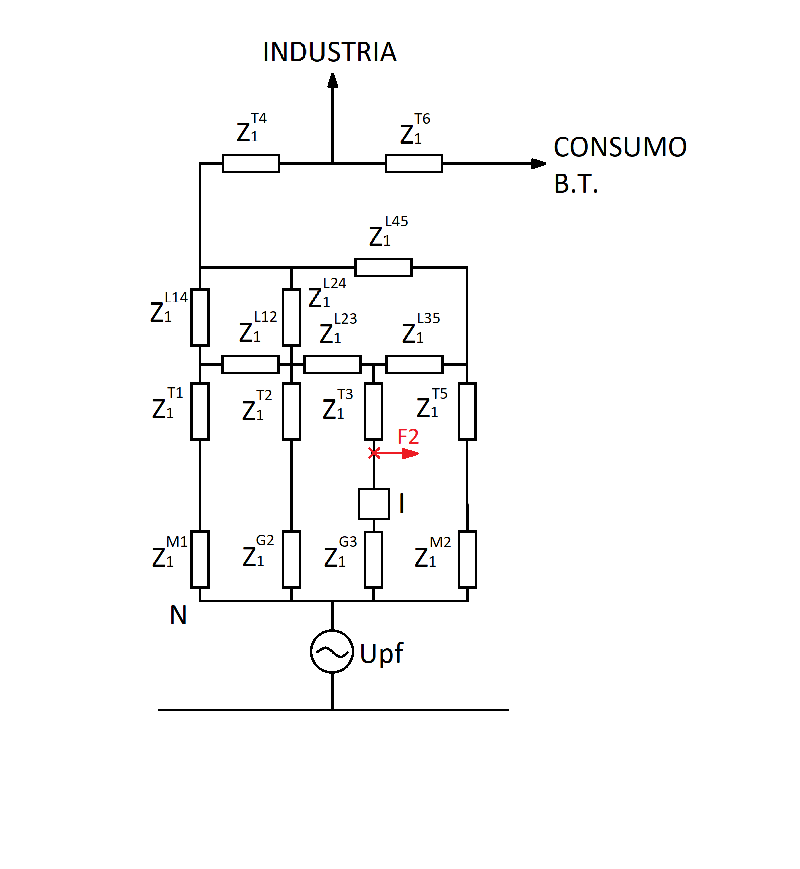

% Datos
Ubase_F2 = Ubase4;
Ibase_F2 = Sbase/(sqrt(3)*Ubase_F2);
Upf_F2 = 1.05;

imshow("F2.png");

## Impedancias necesarias

Como se ve en el esquema anterior, para la corriente del interruptor solo es necesario conocer las corrientes que vienen del generador, por lo que no se trabajará con el resto. Esto se aplica en todas las secuencias.

% Valor por unidad de la impedancia de la rama del interruptor (del generador G3), según todas las secunecias
Z0F2 = ZG3pu(3)

Z0F2 =             0 +        0.1i


Z1F2 = ZG3pu(1)

Z1F2 =             0 +        0.1i


Z2F2 = ZG3pu(2)

Z2F2 =             0 +        0.1i


## Valores de las corrientes de secuencia del interruptor

% Valores por unidad de J012
J1F2_I_pu = Upf_F2/(Z1F2 + Z_paralelo(Z2F2,Z0F2)); % secuencia directa
J2F2_I_pu = -J1F2_I_pu * Z0F2/(Z0F2 + Z2F2); % secuencia inversa (por divisor de corriente)
J0F2_I_pu = -J1F2_I_pu * Z2F2/(Z0F2 + Z2F2); % secuencia homopolar (por divisor de corriente)

% Matriz de corrientes de secuencia (pu)
J012_I_pu = [J0F2_I_pu; J1F2_I_pu; J2F2_I_pu]

J012_I_pu =             0 +        3.5i
            0 -          7i
            0 +        3.5i


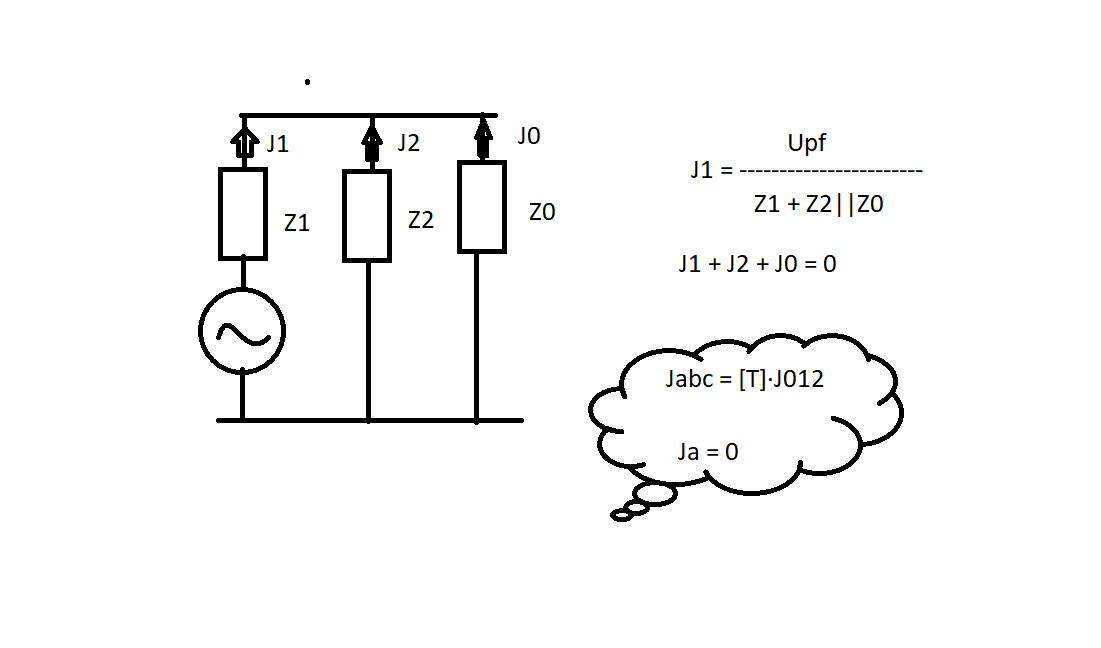


imshow("F2T.png");

## Valores de las corrientes de fase del interruptor

% Valores por unidad
Jabc_I_pu = T*J012_I_pu

Jabc_I_pu =             0 +          0i
      -9.0933 +       5.25i
       9.0933 +       5.25i



% Valores reales en amperios
Jabc_I = Jabc_I_pu*Ibase_F2

Jabc_I =             0 +          0i
       -30882 +      17830i
        30882 +      17830i
